# MATLAB MPC

A, Desbiens, March 2021

clear;

## Plant model

% Sampling period
Ts = 1;

% Parameters
% Shipping delay between the Factory and Retailer [time units]
thetap2 = 3;  

% Retail inventory model
% input u(k) : orders to factory at time k
% output y(k) : inventory level at end of time k
%G = tf(1, [1 -1], Ts, 'IODelay', thetap2, 'Variable', 'z^-1');
%model_ = ss(G);
%model_ = absorbDelay(model_);
%model_ = minreal(model_);

% Factory production lead time [time units]
%thetap1 = 3;

% Factory inventory model
% input u(k) : production starts at time k
% output y(k) : inventory level at end of time k
%G_ = tf(1, [1 -1], Ts, 'IODelay', thetap1, 'Variable', 'z^-1');


% This function produces the equivalent model but with
% 'nicer' coefficients.
[model, G] = int_delay_sys_dt(thetap2, Ts)

model =
 
  A = 
       x1  x2  x3
   x1   1   1   0
   x2   0   0   1
   x3   0   0   0
 
  B = 
       u1
   x1   0
   x2   0
   x3   1
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Sample time: 1 seconds
Discrete-time state-space model.


G =
 
              1
  z^(-3) * --------
           1 - z^-1
 
Sample time: 1 seconds
Discrete-time transfer function.




% Verify both models are the same
% y = impulse(model, 10);
% y_ = impulse(model_, 10);
% assert(all(abs(y - y_) < 1e-12))

n = length(model.A);
nu = size(model.B,2);
ny = size(model.C,1);

## Design MPC Controller

mpcverbosity off;
% Define type of input signals for the plant:
%  MV, Manipulated: input channels 
%  MD, Measured Disturbances: input channels 
%  UD, Unmeasured Disturbances: input channels 
%  MO, Measured Outputs: output channels 
%  UO, Unmeasured Outputs: output channels
model = setmpcsignals(model,'MV',1:1,'UD',3:4,'MO',1:2); % inputs 1 and 2 are MVs

Error using DynamicSystem/set (line 71)
Invalid value for "InputGroup" property. Some input channel index is out of range. Type "DynamicSystem.InputGroup" from more information.

Error in setmpcsignals (line 131)
set(P,'InputGroup',IG,'OutputGroup',OG);

                                                         % inputs 3 and 4 are UDs                                                       % are UDs
                                                         % outputs 1 and 2 are MOs 
% Create the controller object with sampling period (all other parameters by default)
mpcobj = mpc(model,Ts);
%


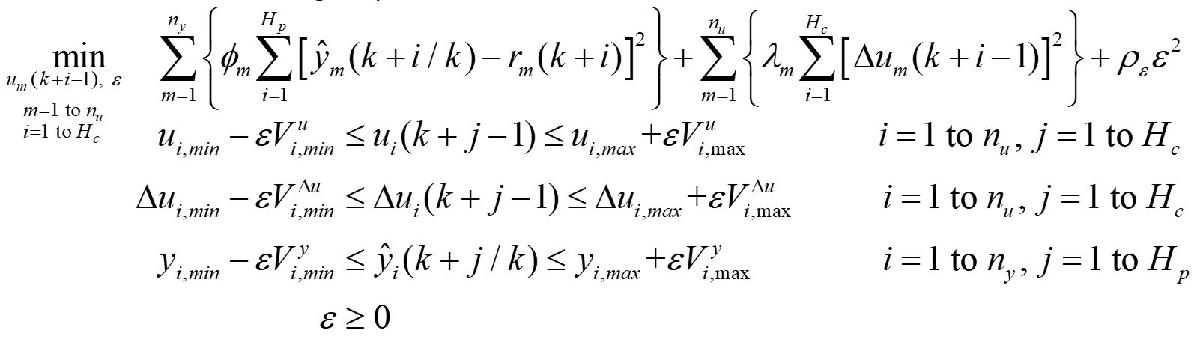

% Main MPC parameters:
%
% Operating points
u_op = [10;20;0;0];
y_op = [30;40];
mpcobj.model.Nominal.U=u_op;
mpcobj.model.Nominal.Y=y_op;
%
%Prediction and control horizons
mpcobj.PredictionHorizon = 20;
mpcobj.ControlHorizon = 1;
%
%constraints and scaling for Mvs
mpcobj.MV = struct('Min',{0,0},'Max',{50,50}, ... % u_1min u_2min   u1max u2max
                   'RateMin',{-10,-10},'RateMax',{10,10}, ... % deltau_1min deltau_2min   deltau_1max deltau_2max
                   'RateMinECR',{0,0},'RateMaxECR',{0,0}, ... % V^deltau_1min V^deltau_2min   V^deltau_1max V^deltau_2max (0 = hard constraints)
                   'MinECR',{0,0},'MaxECR',{0,0}, ... % V^u_1min V^u_2min   V^u_1max V^u_2max (0 = hard constraints)
                   'ScaleFactor',{50,50}); % range of u_1 range of u_2     
%
%constraints and scaling for OVs (OV = OutputVariables = MO + UO - here we only have MOs)
mpcobj.OV = struct('Min',{10,10},'Max',{90,90}, ... %y1min y2min   y1max y2max
                   'MinECR',{1,1},'MaxECR',{1,1}, ...% V^y_1min V^y_2min   V^y_1max V^y_2max (1 = soft constraints)
                   'ScaleFactor',{80,80}); ... % range of y_1 range of y_2      
% Weights
mpcobj.Weights.OutputVariables = [1 1]; % phi1 and phi2
mpcobj.Weights.ManipulatedVariablesRate = [0.1 0.1]; % lambda1 and lambda2
mpcobj.Weights.ECR = 1e5; % rho_epsilon
%

## Design Observer

Some possible ways: 

1: Default observer with input disturbances = integrators driven by white noise with unitary standard deviations 

2: Default observer with integrators driven by white noise with selected standard deviations 

3: Design of our own Luenberger observer 

4: Design of our own steady-state Kalman filter:

observer=1;
% Get output scaling factors
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%sy=[mpcobj.OV(1).ScaleFactor,mpcobj.OV(2).ScaleFactor];
switch observer
    case 1
        setindist(mpcobj,'integrators'); % input disturbances are integrated white noises
    case 2
        % 2a: modindist: model of input disturbances driven by white noise
        % identical to case 1
        modindist=[tf(1,[1 0]) 0; 0 tf(1,[1 0])]; 
        % 2b: faster input disturbance 1 (t = 800) rejection
        %modindist=[tf(5,[1 0]) 0; 0 tf(1,[1 0])]; 
        % 2c: faster input disturbance 2 (t = 1200) rejection
        %modindist=[tf(1,[1 0]) 0; 0 tf(5,[1 0])]; 
        % 2d: both faster
        %modindist=[tf(5,[1 0]) 0; 0 tf(5,[1 0])]; 
        setindist(mpcobj,'model',modindist);  
    case 3
        % augmented model with integrators
        Aaug=[model.A model.B(:,1:nu); zeros(nu,n) eye(nu)];
        Caug=[model.C zeros(ny,nu)];
        %
        % poles_obs: poles of the estimation error dynamics  
        poles_obs=zeros(1,n+nu);
        for i=1:n+nu
            poles_obs(i)=1-i*0.015; % slower disturbance rejection, less sensitive to noise
        end
        %for i=1:n+ny
        %    poles_obs(i)=0.95-i*0.015; % faster disturbance rejection, more sensitive to noise
        %end
        % not obvious to know which modes affect which outputs: we would
        % need a modal observer
        %
        Kpred = place(Aaug',Caug',poles_obs)';
        setEstimator(mpcobj,Kpred);
    case 4
        % augmented model with integrators
        Aaug=[model.A model.B(:,1:nu); zeros(nu,n) eye(nu)];
        Baug=[model.B(:,1:nu); zeros(nu,nu)];
        Caug=[model.C zeros(ny,nu)];
        Daug=[zeros(ny,nu)];       
        %
        % Matrices G and H: seek help kalman 
        G=eye(size(Baug,1));
        H=zeros(size(Caug,1),size(Baug,1));
        %
        % Covariance matrices
        R=0.1*eye(ny); % Measurement noise
        % Q: covariance matrix, process noise
        Q=blkdiag(0.1*eye(n-nu),0.001,0.001);      
        %Q=blkdiag(eye(n-nu),0.001,1); 
        %Q=blkdiag(eye(n-nu),1,0.001); 
        %Q=blkdiag(eye(n-nu),1,1); 
        %
        [~,Kpred] = kalman(ss(Aaug,[Baug G],Caug,[Daug H],Ts),Q,R);
        setEstimator(mpcobj,Kpred);
end

% The creation of the model predictive controller object «mpcobj» is now complete:
mpcobj

## Simulation with Simulink

Tstop = 2400;          % simulation time
t=0:Ts:Tstop-Ts;      % time vector
N = length(t);        % number of simulation steps
%
% Setpoints
r1 = 30+[zeros(50,1); 30*ones(N-50,1)];            
r2 = 40+[zeros(N/6,1); 10*ones(N-N/6,1)];           
r = [r1 r2];          
%
% Input and output disturbances
du1 = [zeros(2*N/6,1); 6*ones(N-2*N/6,1)]; 
du2 = [zeros(3*N/6,1); 6*ones(N-3*N/6,1)];     
du = [du1 du2];                   
dy1 = [zeros(4*N/6,1); 6*ones(N-4*N/6,1)]; 
dy2 = [zeros(5*N/6,1); 6*ones(N-5*N/6,1)];     
dy = [dy1 dy2];  
%
% Simulink
r_sim=[t' r];
du_sim=[t' du];
dy_sim=[t' dy];
open('MPC_Matlab_sim.slx');
sim('MPC_Matlab_sim.slx');


# ADVANCED CODE FOR GEL-7029:

## Simulate Closed-Loop Response Using the SIM Command

% Specify simulation parameters.
SimOptions = mpcsimopt(mpcobj);                       
SimOptions.UnmeasuredDisturbance = du;
SimOptions.OutputNoise = dy;
SimOptions.ShowOutputNoise = 1;    % Does not work...
%
% Run the closed-loop simulation and save the results.
[y,tsim,u,xp] = sim(mpcobj,N,r,[],SimOptions);
%
% Plot results.
figure(1);
subplot(211)
plot(tsim,y,'k-',tsim,r,'r:','linewidth',2)
title('Set-points and CVs (sim)');
text(300,40,'Problem with sim'); % The same problem is present when simulating inside mpcDesigner (it uses sim command)
text(300,37,'with output'); 
text(300,34,'disturbances');
grid
subplot(212)
stairs(tsim,u,'k-','linewidth',2)
title('MVs');
grid

## Simulate MPC with MPCMOVE (for loop)

% First get the discrete-time state-space matrices of the plant.
[A,B,C,D] = ssdata(model);
x = zeros(n,1);                 % Initial state of the plant
u = zeros(nu,1);                % Initial MVs
xmpc = mpcstate(mpcobj);    % Initial state of the MPC controller
%
% Store the closed-loop MPC trajectories in arrays YY,UU.
YY=zeros(2,N);
UU=zeros(2,N);
%
% Create simulation loop
for i=1:N
    % Plant equation: output
    y = C*x + dy(i,:)' + mpcobj.model.Nominal.Y; 
    YY(:,i) = y;
    %     
    % Compute MPC action
    [u, predinfo] = mpcmove(mpcobj,xmpc,y,r(i,1:2)',[]);
    %
    % Plant equations: state update
    x = A*x + B*([u; du(i,:)'] - mpcobj.model.Nominal.U); 
    UU(:,i) = u;
end

% Plot results.
figure(2);
subplot(211)
plot(t,YY,'k-',t,r,'r:','linewidth',2)
grid
title('Set-points and CVs (mpcmove)');
subplot(212)
stairs(t',UU')
stairs(t',UU','k-','linewidth',2)
grid
title('MVs');